# Activity 7: Featured Extraction from Labeled Blobs

#### 01: Different Coins

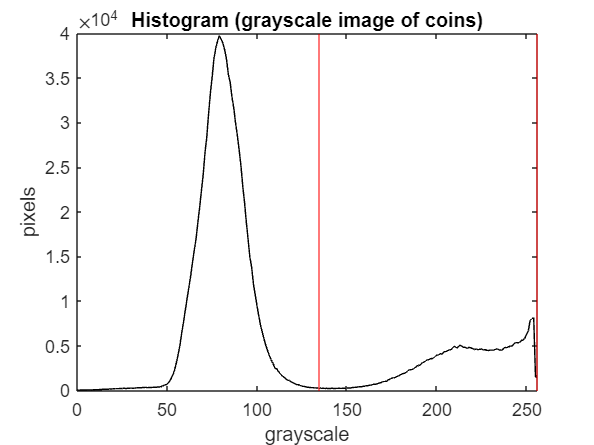

%Histogram
clear;close;
I = rgb2gray(imread('coins.jpeg'));
[count, cells] = imhist(I, 256);
plot(cells, count, 'color', 'black'); ylabel('pixels'); xlabel('grayscale'); xlim([0 256]);
hold on; xline(135, 'color', 'red'); xline(256,'color', 'red');
title('Histogram (grayscale image of coins)');

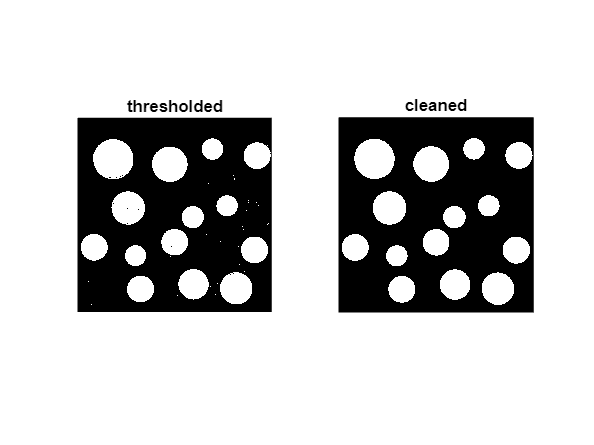

%Thresholding
clear;close;
subplot(1,2,1); imshow(threshold('coins.jpeg',135,256)); title('thresholded');
subplot(1,2,2); imshow(coinclean('coins.jpeg')); title('cleaned');

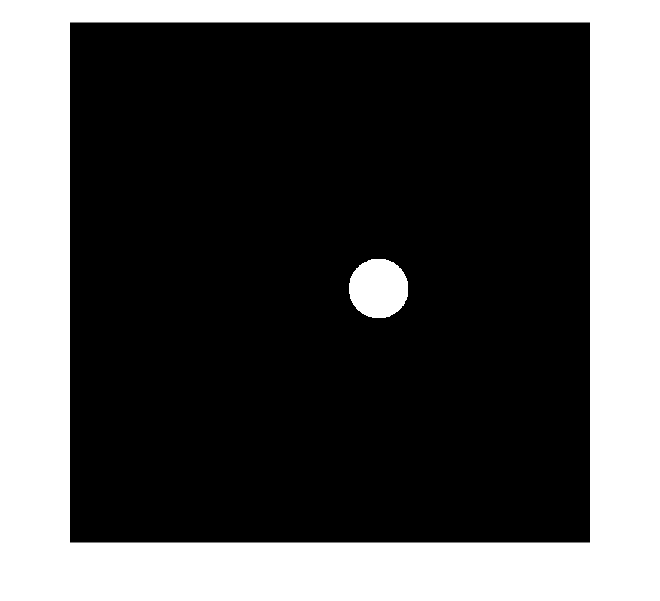

%For the single coins 
clear;close;
BWL = bwlabel(coinclean('coins.jpeg'));
imshow(BWL==9);

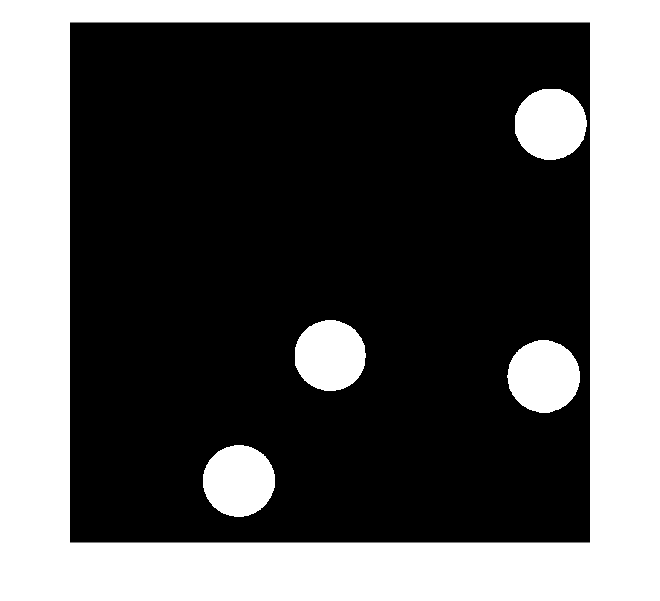

clear;close;
%25 centavo coins
BWL = bwlabel(coinclean('coins.jpeg'));
% Read the input image
image = BWL;

% Create a binary mask of the same size as the input image
mask = false(size(image));

% Define the region of interest
% Here, we'll extract a rectangular region defined by the top-left and bottom-right coordinates
roi_top_left5 = [300, 950];  % [x, y] coordinates of the top-left corner of the region
roi_bottom_right5 = [500, 1200];  % [x, y] coordinates of the bottom-right corner of the region
roi_top_left7 = [520, 700];  % [x, y] coordinates of the top-left corner of the region
roi_bottom_right7 = [700, 880];  % [x, y] coordinates of the bottom-right corner of the region
roi_top_left13 = [1020, 740];  % [x, y] coordinates of the top-left corner of the region
roi_bottom_right13 = [1200, 920];  % [x, y] coordinates of the bottom-right corner of the region
roi_top_left14 = [1040, 140];  % [x, y] coordinates of the top-left corner of the region
roi_bottom_right14 = [1220, 340];  % [x, y] coordinates of the bottom-right corner of the region

% Set the pixels within the region of interest to true in the mask
mask(roi_top_left5(2):roi_bottom_right5(2), roi_top_left5(1):roi_bottom_right5(1)) = true;
mask(roi_top_left7(2):roi_bottom_right7(2), roi_top_left7(1):roi_bottom_right7(1)) = true;
mask(roi_top_left13(2):roi_bottom_right13(2), roi_top_left13(1):roi_bottom_right13(1)) = true;
mask(roi_top_left14(2):roi_bottom_right14(2), roi_top_left14(1):roi_bottom_right14(1)) = true;
% Apply the mask to the input image
masked_image = image;
masked_image(~repmat(mask, [1, 1, size(image, 3)])) = 0;

% Display the masked image
imshow(masked_image);

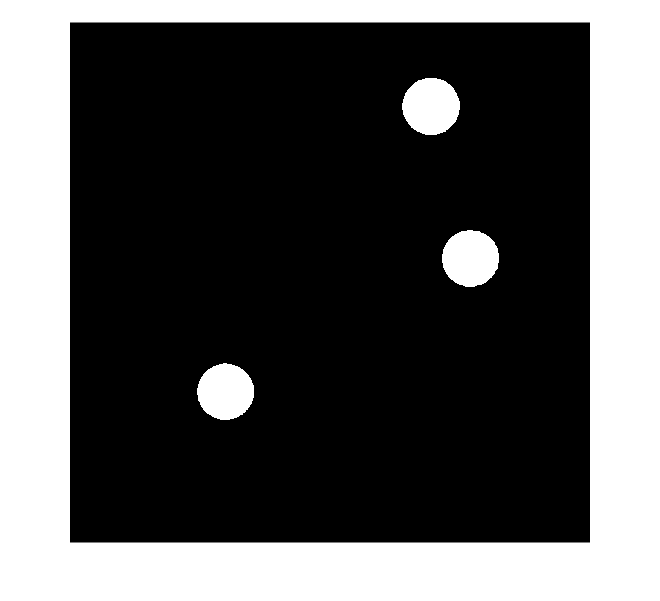

clear;close;
%5 centavo coins
BWL = bwlabel(coinclean('coins.jpeg'));
% Read the input image
image = BWL;

% Create a binary mask of the same size as the input image
mask = false(size(image));

% Define the region of interest
% Here, we'll extract a rectangular region defined by the top-left and bottom-right coordinates
roi_top_left4 = [280, 780];  % [x, y] coordinates of the top-left corner of the region
roi_bottom_right4 = [460, 960];  % [x, y] coordinates of the bottom-right corner of the region
roi_top_left10 = [750, 100];  % [x, y] coordinates of the top-left corner of the region
roi_bottom_right10 = [950, 300];  % [x, y] coordinates of the bottom-right corner of the region
roi_top_left11 = [850, 460];  % [x, y] coordinates of the top-left corner of the region
roi_bottom_right11 = [1050, 660];  % [x, y] coordinates of the bottom-right corner of the region

% Set the pixels within the region of interest to true in the mask
mask(roi_top_left4(2):roi_bottom_right4(2), roi_top_left4(1):roi_bottom_right4(1)) = true;
mask(roi_top_left10(2):roi_bottom_right10(2), roi_top_left10(1):roi_bottom_right10(1)) = true;
mask(roi_top_left11(2):roi_bottom_right11(2), roi_top_left11(1):roi_bottom_right11(1)) = true;

% Apply the mask to the input image
masked_image = image;
masked_image(~repmat(mask, [1, 1, size(image, 3)])) = 0;

% Display the masked image
imshow(masked_image);

BWL = bwlabel(coinclean('coins.jpeg'));
features = regionprops("table", BWL, ...
    "Centroid", "MajorAxisLength", "MinorAxisLength", "Area")

features = 14×4 table
    Area         Centroid        MajorAxisLength    MinorAxisLength
    _____    ________________    _______________    _______________

    22110    106.11    814.31        168.45             167.13     
    50048    225.83    260.78        253.72             251.17     
    34582    319.94    567.62        210.79              208.9     
    13802    365.69    866.94        133.41             131.74     
    22347    396.78    1076.2        169.56             167.81     
    38991    580.26    292.59        222.98             222.65     
    21935    610.97    782.16        167.73             166.53     
    28479    729.39    1046.4           191             189.86     
    15415    724.65    624.78        140.28             139.92     
    14202    847.72    197.34        134.64             134.31     
    14040    940.05    55

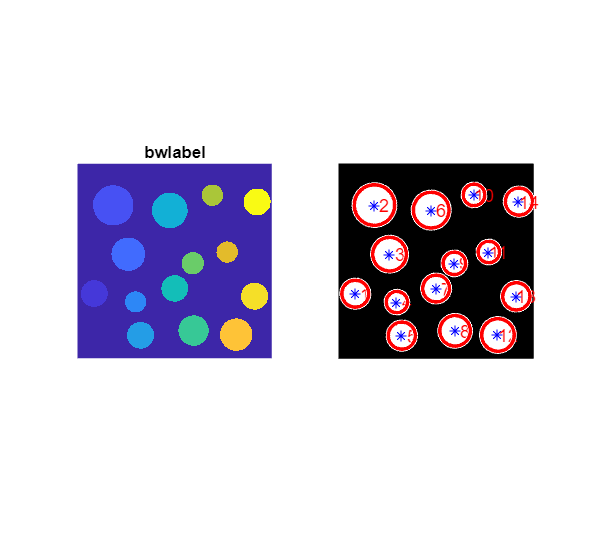

subplot(1,2,1);
imagesc(BWL); axis image; axis off; title("bwlabel");
subplot(1,2,2);
coinproperties(BWL, features);

#### 02: Dice 

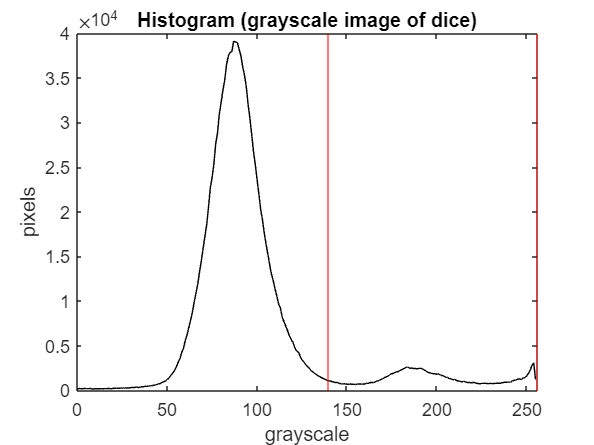

clear;close;
I = rgb2gray(imread('dice.jpeg'));
[count, cells] = imhist(I, 256);
plot(cells, count, 'color', 'black'); ylabel('pixels'); xlabel('grayscale'); xlim([0 256]);
hold on; xline(140, 'color', 'red'); xline(256,'color', 'red');
title('Histogram (grayscale image of dice)');

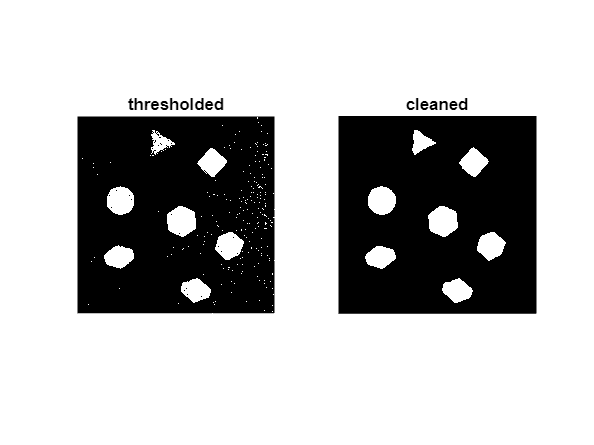

clear; close;
subplot(1,2,1);
imshow(threshold('dice.jpeg',140,256)); title('thresholded');
subplot(1,2,2); imshow(diceclean('dice.jpeg')); title('cleaned');

close;clear;
BWL = bwlabel(diceclean('dice.jpeg'));
features = regionprops("table", BWL, "Centroid", "BoundingBox", "Circularity", "MajorAxisLength", "MinorAxisLength")

features = 7×5 table
        Centroid                    BoundingBox                MajorAxisLength    MinorAxisLength    Circularity
    ________________    ___________________________________    _______________    _______________    ___________

    262.44    881.28    167.5     812.5       190       142        187.52             132.85           0.92433  
    270.97    528.55    183.5     439.5       174       178        177.65             175.33            1.0026  
    515.59    164.71    459.5      86.5       149       157        136.41             135.97           0.61558  
    652.88    657.77    561.5     559.5       184       196        187.28             186.15           0.96421  
    741.68    1090.1    647.5    1014.5       189       153        185.05              137.2           0.90786  
    844.11    290

diameter = mean([features.MajorAxisLength features.MinorAxisLength], 2)/(1220/150)

diameter =    19.6947
   21.6995
   16.7444
   22.9571
   19.8100
   19.8387
   20.6778


T = table(features.Circularity, diameter, VariableNames= ["Circularity", "Diameter"])

T = 7×2 table
    Circularity    Diameter
    ___________    ________

      0.92433       19.695 
       1.0026         21.7 
      0.61558       16.744 
      0.96421       22.957 
      0.90786        19.81 
      0.85943       19.839 
      0.94273       20.678 


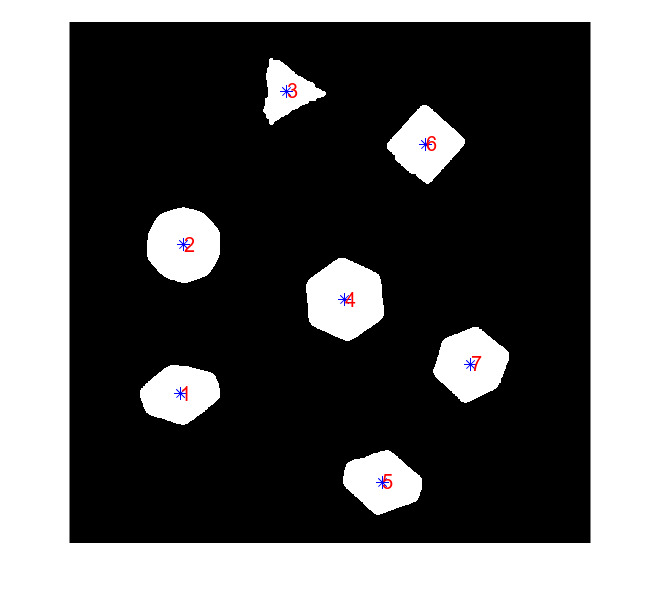

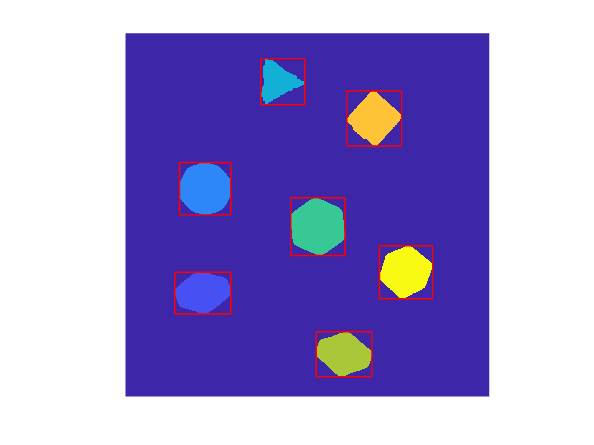

properties(BWL, features);

#### 03: Rice Grains

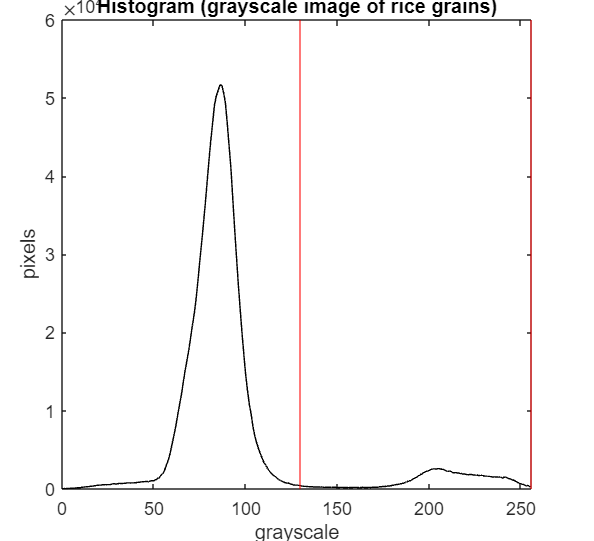

clear;close;
I = rgb2gray(imread('ricee.jpeg'));
[count, cells] = imhist(I, 256);
plot(cells, count, 'color', 'black'); ylabel('pixels'); xlabel('grayscale'); xlim([0 256]);
hold on; xline(130, 'color', 'red'); xline(256,'color', 'red');
title('Histogram (grayscale image of rice grains)');

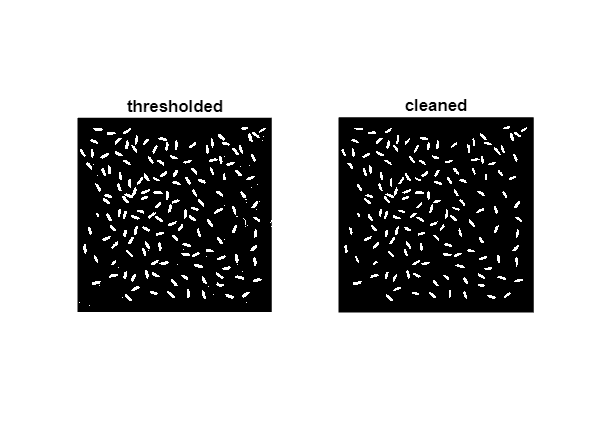

clear;close;
subplot(1,2,1); 
imshow(threshold('ricee.jpeg', 130, 256)); title('thresholded')
subplot(1,2,2);
imshow(riceclean('ricee.jpeg')); title('cleaned');

%extract features
clear;close;
BWL = bwlabel(riceclean('ricee.jpeg'));
features = regionprops("table", BWL, "Centroid", "BoundingBox", "Perimeter", "Circularity", "MajorAxisLength", "MinorAxisLength")

features = 145×6 table
        Centroid                    BoundingBox                MajorAxisLength    MinorAxisLength    Circularity    Perimeter
    ________________    ___________________________________    _______________    _______________    ___________    _________

    33.905    221.05     19.5     195.5        31        49        56.067             16.458           0.63808       118.08  
    48.412    824.08     38.5     795.5        19        57        58.269             18.406           0.66624       124.97  
    76.098    302.51     56.5     283.5        36        41        52.575             17.792           0.69149       113.75  
    78.775    710.47     67.5     687.5        22        46        48.978             16.808           0.69514       106.72  
    105.25    14

diameter = mean([features.MajorAxisLength features.MinorAxisLength], 2)

diameter =    36.2627
   38.3377
   35.1835
   32.8932
   35.4498
   36.2251
   39.6038
   38.2011
   31.8705
   37.5669


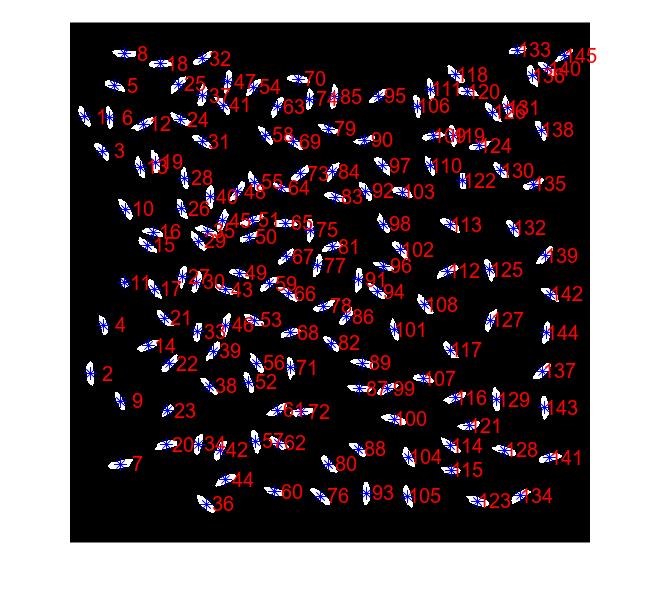

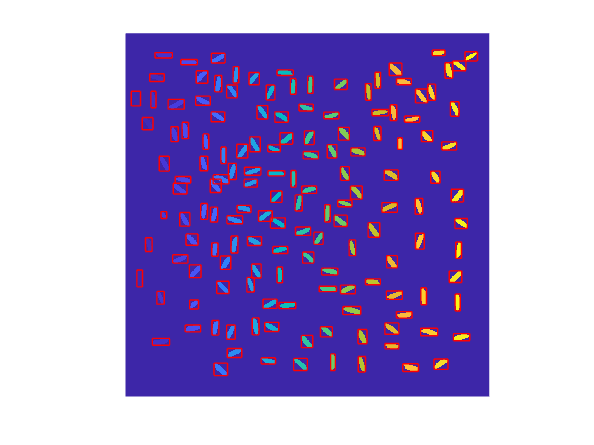

properties(BWL, features);

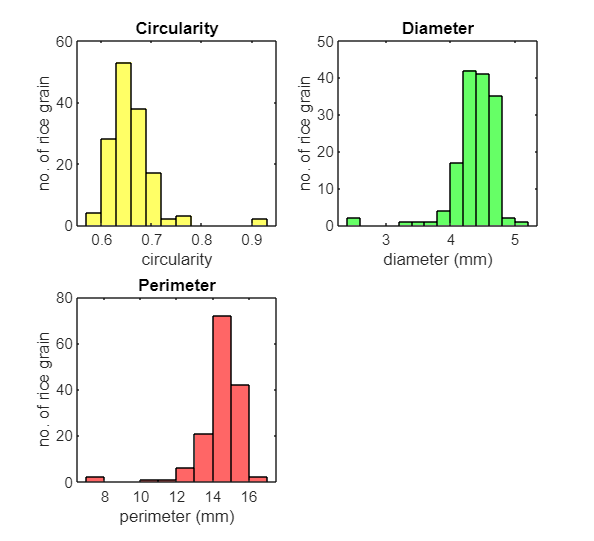

clear;close;
rawTable = readtable('feature_extraction.xlsx', 'Sheet', 'Sheet2');

circularity = rawTable.Circularity;
diameter = rawTable.Diametermm;
perimeter = rawTable.Perimetermm;
subplot(2,2,1);
histogram(circularity, "FaceColor", "Yellow"); title("Circularity"); xlabel("circularity"); ylabel("no. of rice grain");
subplot(2,2,2);
histogram(diameter, "FaceColor", "Green"); title("Diameter"); xlabel("diameter (mm)");ylabel("no. of rice grain");
subplot(2,2,3);
histogram(perimeter, "FaceColor", "Red"); title("Perimeter"); xlabel("perimeter (mm)");ylabel("no. of rice grain");

function BW =threshold(image,threshold1, threshold2)
    I = rgb2gray(imread(image));
    BW = and(I < threshold2, I > threshold1);
end
function BW5 = coinclean(image)
    BW1 = imopen(threshold(image,130,256), strel("disk", 2));
    BW2 = imclose(BW1, strel("disk",2));
    BW3 = imopen(BW2, strel("disk",3));
    BW4 = imclose(BW3, strel("disk",3));
    BW5 = bwmorph(BW4, "fill");
end
function BW5 = diceclean(image)
    BW1 = imopen(threshold(image,125,256), strel("disk", 2));
    BW2 = imclose(BW1, strel("disk",2));
    BW3 = bwmorph(BW2, "fill");
    BW4 = imopen(BW3, strel("disk",6));
    BW5 = imclose(BW4, strel("disk",6));
end
function BW4 = riceclean(image)
    BW1 = imclose(threshold(image, 160, 256), strel("disk",1));
    BW2 = bwmorph(BW1, 'thin');
    BW3 = bwmorph(BW2, 'fill');
    BW4 = imopen(BW3, strel("disk",1));
end
function centroid = coinproperties(image, x)
    centroid = cat(1, x.Centroid);
    center = x.Centroid;
    diameter = mean([x.MajorAxisLength x.MinorAxisLength], 2);
    radii = diameter/2;
    imshow(image);
    hold on;
    plot(centroid(:,1), centroid(:,2), 'b*');
    
    % Add label numbers to centroids
    labels = 1:size(centroid, 1);
    text(centroid(:, 1), centroid(:, 2), num2str(labels'), 'Color', 'red');
    viscircles(center, radii);

    hold off;
end
function centroid = properties(image, x)
    centroid = cat(1, x.Centroid);
    imshow(image);
    hold on;
    plot(centroid(:,1), centroid(:,2), 'b*');
    
    % Add label numbers to centroids
    labels = 1:size(centroid, 1);
    text(centroid(:, 1), centroid(:, 2), num2str(labels'), 'Color', 'red');

    hold off;

    figure(); imagesc(image); hold on; axis off; axis image; 
    bounding_box = cat(1,x.BoundingBox);
    for i= 1:size(x,1)
        rectangle('Position', bounding_box(i,:), 'EdgeColor', 'r');
    end
end